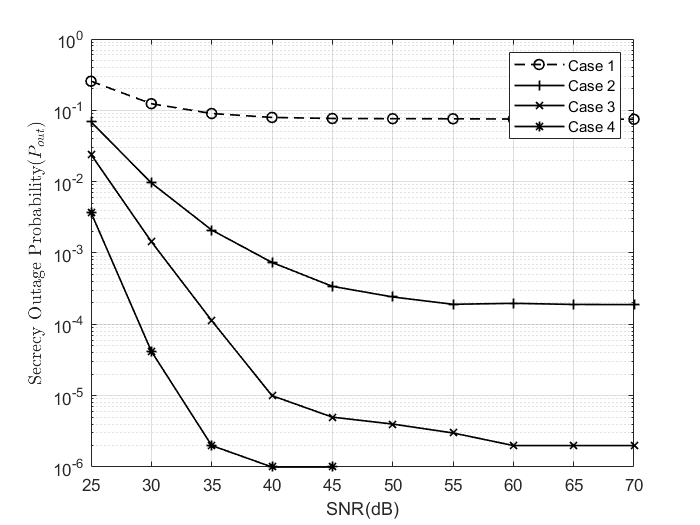

%最后一版可信个数对安全性能的影响
x=[25;30;35;40;45;50;55;60;65;70];
NoTrustedNode=[0.256013,0.1238,0.090245,0.079562,0.076864,0.076369,0.076119,0.075518,0.075959,0.074955];
OneTrustedNode=[6.9e-2,9.6e-3,2.1e-3,7.37e-4,3.41e-4,2.42e-4,1.91e-4,1.97e-4,1.9e-4,1.89e-4];
TwoTrustedNode=[2.4064e-2,1.443e-3,1.13e-4,1e-05,5e-06,4.e-06,3e-06,2e-06,2e-06,2e-06];
threeTrustedNode=[3.7e-3,4.2e-5,2e-6,1e-6,1e-6,0,0,0,0,0];
% NotTrustProbability=[0.09083,0.012658,0.002495,0.001568,0.001297,0.001246,0.001179,0.00125,0.001318,0.00123];
% FullTrustProbability=[0.018021,0.001204,0.000156,0.00006,0.000031,0.000027,0.000022,0.000027,0.000024,0.000024];

semilogy(x,NoTrustedNode,'--ok','LineWidth',1);
hold on;
%三个中继：0.5，0.4，0.3

semilogy(x,OneTrustedNode,'-+k','LineWidth',1);
hold on;
% 四个中继：1，0。5，0.4，0.3

semilogy(x,TwoTrustedNode,'-xk','LineWidth',1);
% hold on;
% 五个中继：1，1，0.5，0.4，0.3
semilogy(x,threeTrustedNode,'-*k','LineWidth',1);
 hold on;
% 六个中继 1,1,1,0.5,0.4和0.3

% title('');
xlabel('SNR(dB)');
ylabel('Secrecy Outage Probability($P_{out}$)','Interpreter','latex');
handle=legend('Case 1','Case 2','Case 3','Case 4');
grid on